run("complete/complete_parameters.m"); % Load parameters

% Initial state
X0 = [0; 0; 0; 0]

X0 =      0
     0
     0
     0


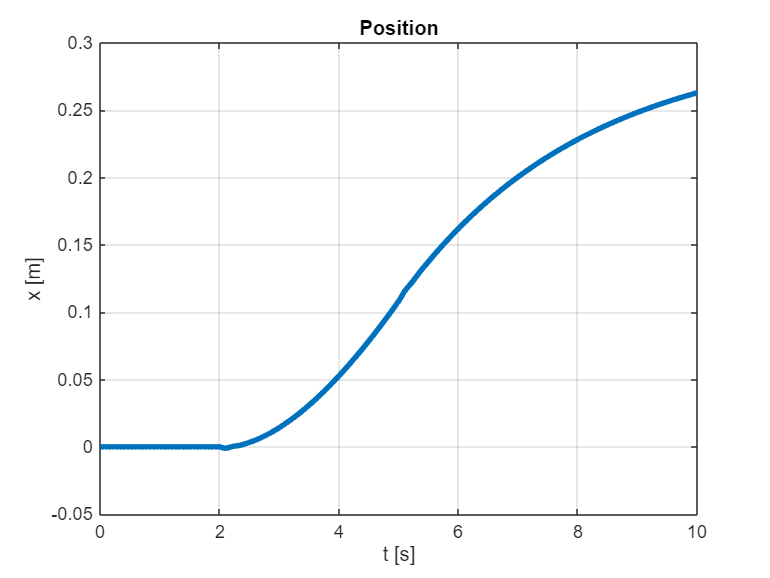

% SIMULINK
% Regulator (Inner Loop)
Kp_t = -2;
Td_t = -0.05;
Ti_t = 0;

% Regulator (Outer Loop)
Kp_v = 0.05;
Td_v = 0;
Ti_v = 0;

% Time vector
t = 0:0.01:10;
Tsim = 10;

% Speed input
v_ref = zeros(size(t));     
v_ref(t >= 2 & t <= 5) = 0.1;

input_signal = [t' v_ref'];

out = sim("complete/complete_robot_sim.slx");

x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
theta_v = out.simout.signals.values(:,3);
dtheta_v = out.simout.signals.values(:,4);
torque_v = out.torque_sim.signals.values();
accel_v = out.accel_sim.signals.values();
lin_accel_v = out.physics_out.signals.values(2,:);
t_v = out.tout;


% x
figure;
plot(t_v, x_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('x [m]');
title('Position');
grid on;

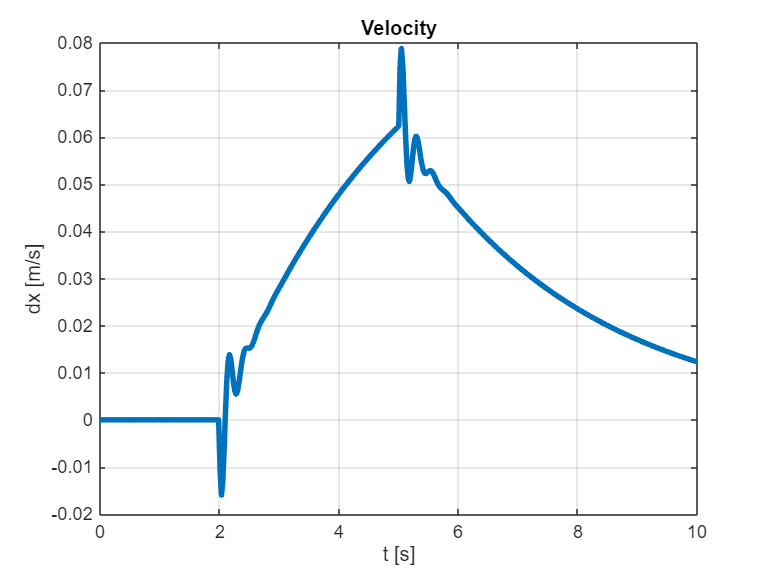


% dx
figure;
plot(t_v, dx_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
grid on;

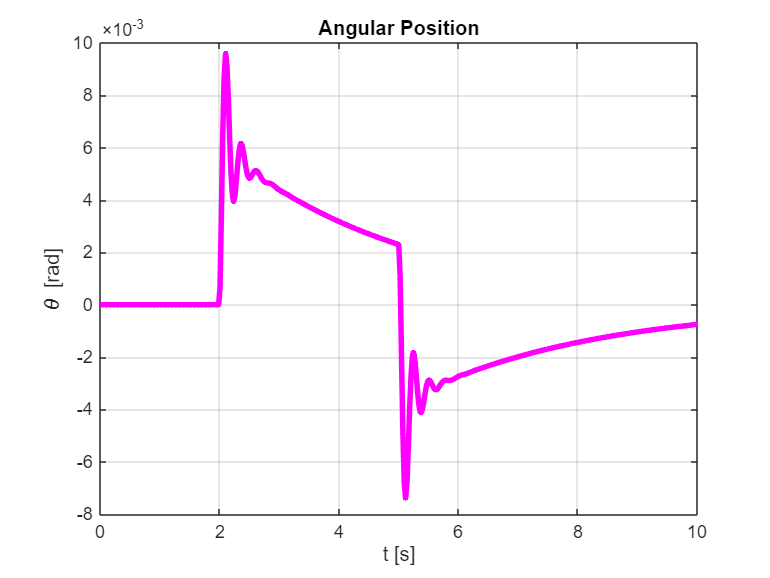



% theta
figure;
plot(t_v, theta_v, "LineWidth", 3,"Color","magenta");
xlabel('t [s]');
ylabel('\theta [rad]');
title('Angular Position');
grid on;

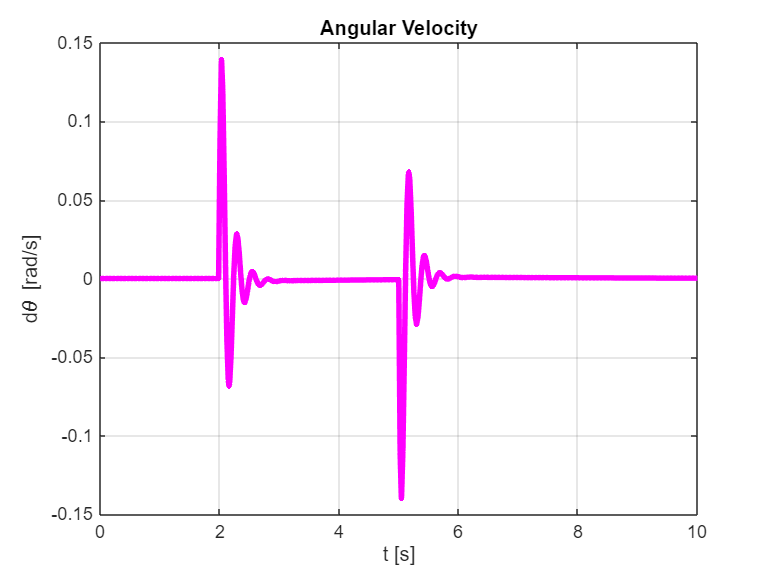


% dtheta
figure;
plot(t_v, dtheta_v, "LineWidth", 3,"Color","magenta");
xlabel('t [s]');
ylabel('d\theta [rad/s]');
title('Angular Velocity');
grid on;

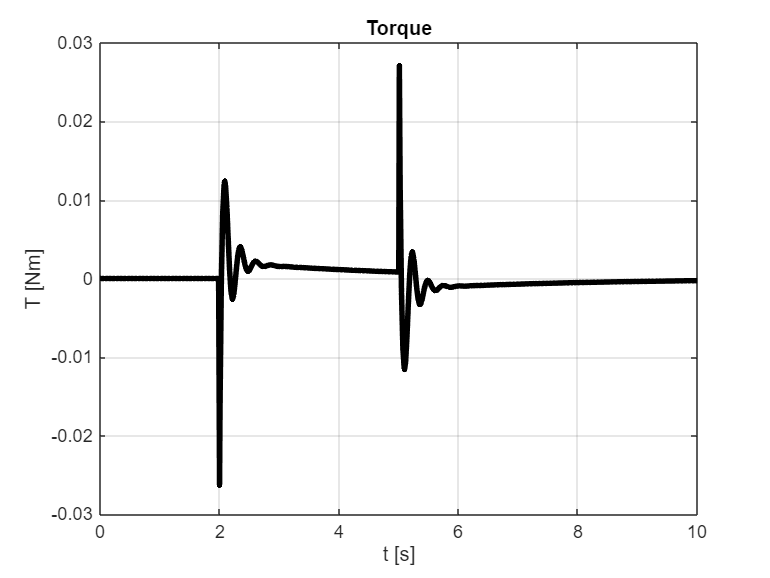

% Torque
figure;
plot(t_v, torque_v, "LineWidth", 3,"Color","black");
xlabel('t [s]');
ylabel('T [Nm]');
title('Torque');
grid on;

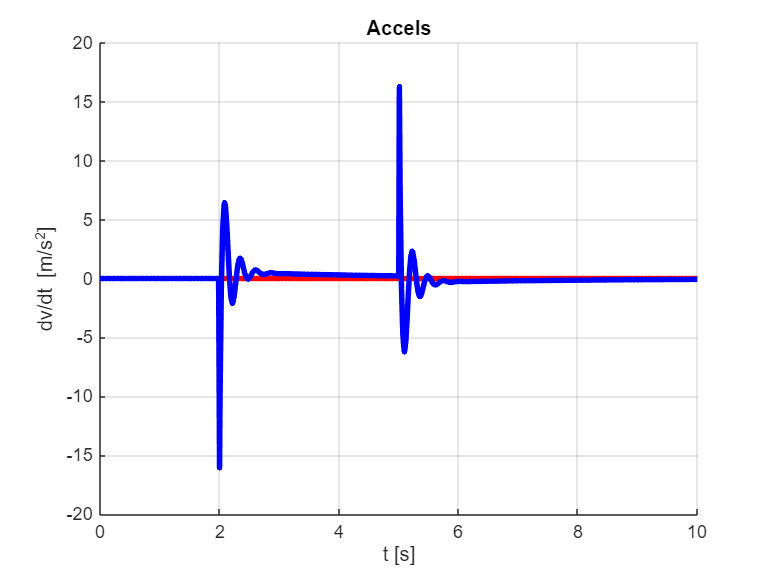

figure;
hold on;
plot(t_v, accel_v, "LineWidth", 3,"Color","red");
plot(t_v, lin_accel_v, "LineWidth", 3,"Color","blue");
xlabel('t [s]');
ylabel('dv/dt [m/s^2]');
title('Accels');
grid on;
hold off;